# Exam January 11, 2018

## Exercise 1

%Panda robot
clear ; close all
q = sym('q',[1 7])

$$q = \left(\begin{array}{ccccccc} q_{1} & q_{2} & q_{3} & q_{4} & q_{5} & q_{6} & q_{7} \end{array}\right)$$

al = pi/2; % rotation 
%a = 3
%d = 10
syms a d 
dh = [al 0 d q(1);
      -al 0 0 q(2);
      al a d q(3);
      -al -a 0 q(4);
      al 0 d q(5);
      al a 0 q(6);
        0 0 d q(7);]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d & q_{1}\\ -\frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & a & d & q_{3}\\ -\frac{\pi }{2} & -a & 0 & q_{4}\\ \frac{\pi }{2} & 0 & d & q_{5}\\ \frac{\pi }{2} & a & 0 & q_{6}\\ 0 & 0 & d & q_{7} \end{array}\right)$$


[T1 Tpartial] = getTranslationMatrix(dh,'alpha')

Tpartial = 1×7 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


[T2 Tpartial2] = getTranslationMatrix(dh.*[-ones(7,1) ones(7,3)],'alpha')

Tpartial2 = 1×7 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


dh = subs(dh,[a d],[10 100])    

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 100 & q_{1}\\ -\frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & 10 & 100 & q_{3}\\ -\frac{\pi }{2} & -10 & 0 & q_{4}\\ \frac{\pi }{2} & 0 & 100 & q_{5}\\ \frac{\pi }{2} & 10 & 0 & q_{6}\\ 0 & 0 & 100 & q_{7} \end{array}\right)$$

%dh = subs(dh,[a d],[10 100])


T1-T2


dht = getDHforTB(dh,'alpha')

n = 7

dht =          0  100.0000         0    1.5708
         0         0         0   -1.5708
         0  100.0000   10.0000    1.5708
         0         0  -10.0000   -1.5708
         0  100.0000         0    1.5708
         0         0   10.0000    1.5708
         0  100.0000         0         0



r = SerialLink(dht)

 
r = 
 
noname:: 7 axis, RRRRRRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        100|          0|     1.5708|          0|
|  2|         q2|          0|          0|    -1.5708|          0|
|  3|         q3|        100|         10|     1.5708|          0|
|  4|         q4|          0|        -10|    -1.5708|          0|
|  5|         q5|        100|          0|     1.5708|          0|
|  6|         q6|          0|         10|     1.5708|          0|
|  7|         q7|        100|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


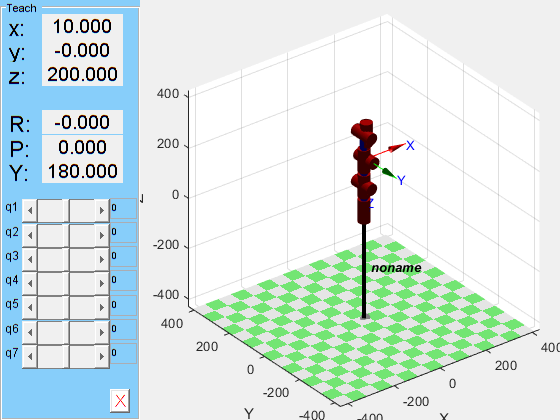

r.teach

## Exercise 4

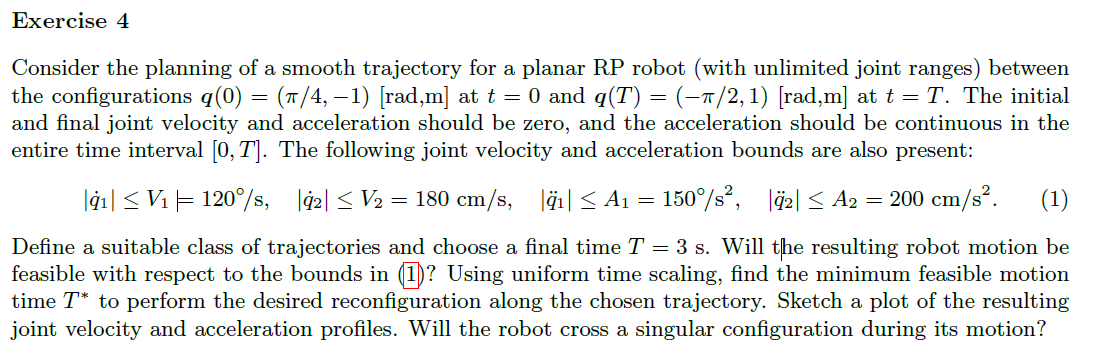

q_0 = sym('q_0',[2,1])

$$q\_0 = \left(\begin{array}{c} q_{01}\\ q_{02} \end{array}\right)$$

q_delta = sym('q_delta',[2,1])

$$q\_delta = \left(\begin{array}{c} q_{\mathrm{delta1}}\\ q_{\mathrm{delta2}} \end{array}\right)$$

tau - sym('tau',[2,1])

$$ans = \left(\begin{array}{c} \tau -\tau_{1}\\ \tau -\tau_{2} \end{array}\right)$$


q_0_val = [pi/4;-1];
q_delta_val = [-pi/2-pi/4; 1-(-1)] 

q_delta_val =    -2.3562
    2.0000


q_tau = q_0 + q_delta*(6*tau^5 -15*tau^4 + 10*tau^3 )

$$q\_tau = \left(\begin{array}{c} q_{01}+q_{\mathrm{delta1}}\,\left(6\,\tau^{5}-15\,\tau^{4}+10\,\tau^{3}\right)\\ q_{02}+q_{\mathrm{delta2}}\,\left(6\,\tau^{5}-15\,\tau^{4}+10\,\tau^{3}\right) \end{array}\right)$$

qd_tau = diff(q_tau)

$$qd\_tau = \left(\begin{array}{c} q_{\mathrm{delta1}}\,\left(30\,\tau^{4}-60\,\tau^{3}+30\,\tau^{2}\right)\\ q_{\mathrm{delta2}}\,\left(30\,\tau^{4}-60\,\tau^{3}+30\,\tau^{2}\right) \end{array}\right)$$

qdd_tau = diff(qd_tau)

$$qdd\_tau = \left(\begin{array}{c} q_{\mathrm{delta1}}\,\left(120\,\tau^{3}-180\,\tau^{2}+60\,\tau \right)\\ q_{\mathrm{delta2}}\,\left(120\,\tau^{3}-180\,\tau^{2}+60\,\tau \right) \end{array}\right)$$

qddd_tau = diff(qdd_tau)

$$qddd\_tau = \left(\begin{array}{c} q_{\mathrm{delta1}}\,\left(360\,\tau^{2}-360\,\tau +60\right)\\ q_{\mathrm{delta2}}\,\left(360\,\tau^{2}-360\,\tau +60\right) \end{array}\right)$$

tau_a_max = solve(qddd_tau == [0;0])

tau_a_max = struct with fields:
    q_delta1: [2×1 sym]
         tau: [2×1 sym]


a_max = eval(subs( qdd_tau , tau , tau_a_max))

Error using sym/subs>normalize (line 217)
Substitution expression X must be a symbolic, cell, or numeric array.

Error in sym/subs>mupadsubs (line 157)
[X2,Y2,symX,symY] = normalize(X,Y); %#ok

Error in sym/subs (<a href

10*sqrt(3)/3

ans = 5.7735

q = sym('q',[1,2])

$$q = \left(\begin{array}{cc} q_{1} & q_{2} \end{array}\right)$$

dhTable = [-pi/2,0,0,q(1);
           pi/2,0,q(2),0];
T = getTransformationMatrix(dhTable,'alpha')

$$T = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & -q_{2}\,\sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & q_{2}\,\cos\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

q_tau_subs = subs(q_tau,[q_0, q_delta],[q_0_val, q_delta_val])

$$q\_tau\_subs = \left(\begin{array}{c} \frac{\pi }{4}-\frac{3\,\pi \,\left(6\,\tau^{5}-15\,\tau^{4}+10\,\tau^{3}\right)}{4}\\ 12\,\tau^{5}-30\,\tau^{4}+20\,\tau^{3}-1 \end{array}\right)$$

qd_tau_subs = subs(qd_tau,[q_0, q_delta],[q_0_val, q_delta_val])

$$qd\_tau\_subs = \left(\begin{array}{c} -\frac{3\,\pi \,\left(30\,\tau^{4}-60\,\tau^{3}+30\,\tau^{2}\right)}{4}\\ 60\,\tau^{4}-120\,\tau^{3}+60\,\tau^{2} \end{array}\right)$$

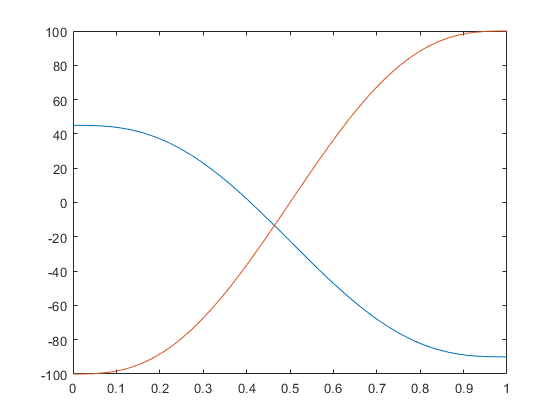

fplot(q_tau_subs.*[180/pi; 100],[0,1])

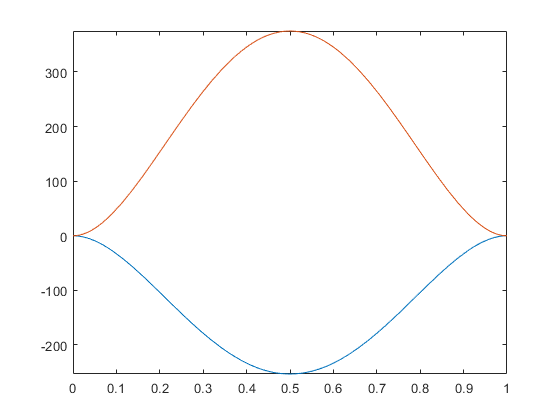

fplot(qd_tau_subs.*[180/pi; 100],[0,1]) % 